# sSC42025 Filtering & Identification

#### MATLAB EXERCISE HW1

#### Instructions: Fill in the live script with your code and answers. Then export the live script as a pdf (in the 'Live Editor tab', click on the arrow under 'Save' and then 'Export to pdf').

You are given measurements $y\in\mathbb{R}^{100\times 1}$. Assuming the measurement model


$$    y = F
    \left[ \matrix{x_1 \cr x_2} \right] +
     \epsilon, \qquad \epsilon\sim\mathcal{N}(0,R),$$


with $F\in\mathbb{R}^{100\times 2}$ and $R=\sigma_y^2I
$, $\sigma_y=0.5$, you would like to find an estimate for $[ x_1 \;\; x_2 ]^\top$. You also have a prior given by 


$$\theta \sim \mathcal{N}\left([1.1 \; \; 1.1]^\top, \left[\matrix{
    0.1 & 0 \cr 0 & 0.1}
    \right]\right).$$


Note that this is a difficult estimation problem, since some measurements have a small signal-to-noise ratio, in other words, $$F$$ is different in each row.

### Exercise 1: Batch estimation

Compute the stochastic least squares estimate $[ \hat{x_1} \;\;\hat{ x_2} ]^\top$ using the given matrices $\texttt{y.mat}$ and $\texttt{F.mat}$ provided in $\texttt{data.mat}
$. Print the result.

clear; clc; close all;

load('data1.mat')
N       = 100;
invP0   = 10*eye(2);
x0      = [1.1; 1.1];
sigy    = .5;
R       = sigy^2*eye(size(F,1));

P_theta = [0.1 0; 0 0.1];
% P_theta is positive definite obviously but i already wrote the code so im
% not gonna change it
K = P_theta * F.' / (F* P_theta * F.' + R)

K =     0.0076   -0.0197    0.0056    0.0156    0.0002   -0.0054   -0.0159    0.0079   -0.0105   -0.0098    0.0099    0.0262   -0.0175    0.0001    0.0079    0.0006    0.0151   -0.0113    0.0156    0.0053    0.0015   -0.0196   -0.0072    0.0034   -0.0032   -0.0027    0.0023    0.0004    0.0012    0.0052    0.0041    0.0015    0.0137   -0.0079   -0.0155   -0.0063   -0.0069    0.0209   -0.0173    0.0043    0.0029    0.0078   -0.0175    0.0212   -0.0045    0.0106   -0.0132    0.0320   -0.0069   -0.0203
   -0.0102   -0.0026    0.0048    0.0081    0.0034   -0.0220   -0.0037    0.0015   -0.0068   -0.0006    0.0066   -0.0050   -0.0101   -0.0074   -0.0044   -0.0097    0.0094   -0.0041   -0.0247    0.0056   -0.0011    0.0043   -0.0158   -0.0117    0.0027   -0.0142   -0.0139    0.0016   -0.0136   -0.0039    0.0109    0.0055    0.0023    0.0000   -0.0204    0.0116    0.0019    0.0069   -0.0006    0.0168    0.0038    0.0046   -0.0104   -0.0014    0.0034   -0.0101   -0.0022   -0.0098   -0.0002    0

theta_hat = K* y + (eye(2) - K*F) * x0

theta_hat =     1.1397
    1.1721


### Exercise 2: Recursive estimation

Compute the recursive least squares estimate, pretending that one measurement becomes available at a time. Print the result.

P_new = P_theta

P_new =     0.1000         0
         0    0.1000


theta_new = [1.1,; 1.1]

theta_new =     1.1000
    1.1000



t_history = zeros(100, 2);
for i = (1:100)
    F_loop = F(i, :);
    y_loop = y(i, :);
    R_loop = R(i, i);
    K_new = P_new * F_loop.' / (F_loop* P_new * F_loop.' + R_loop);
    theta_new = K_new*y_loop + (eye(2) - K_new*F_loop) * theta_new;
    P_new = P_new - K_new * F_loop * P_new;
    t_history(i, :) = theta_new;
end

theta_new

theta_new =     1.1397
    1.1721


### Exercise 3: Visualization

Plot the results of a) and b) **into the same figure**. For b) plot the path connecting the estimates for each recursion step. Note that the recursive estimation should obtain the exact same result as the batch estimation. Also plot the ground truth, which is given by $[1.2 \;\; 1.2]$. You could set the x-axis to represent estimate for $
x_1 $ and the y-axis to represent estimate for $
x_2$ in the figure.

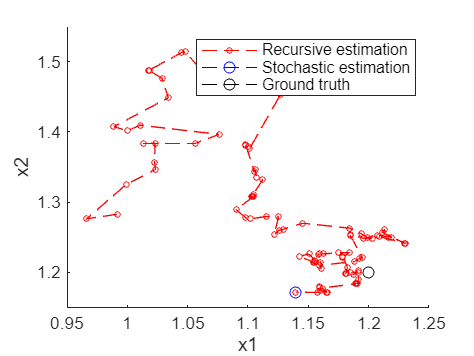

hold on
plot(t_history(:, 1), t_history(:, 2), '--ro', MarkerSize=3, DisplayName="Recursive estimation")
plot(theta_hat(1), theta_hat(2), '--bo', DisplayName="Stochastic estimation")
plot(1.2, 1.2, "--ko", DisplayName="Ground truth")
xlabel('x1')
ylabel('x2')
legend()
hold off